# Train Network with Augmented Images

Train a convolutional neural network using augmented image data. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.

Load the sample data, which consists of synthetic images of handwritten digits.

[XTrain,YTrain] = digitTrain4DArrayData;

`digitTrain4DArrayData` loads the digit training set as 4-D array data. `XTrain` is a 28-by-28-by-1-by-5000 array, where:

- 28 is the height and width of the images. 

- 1 is the number of channels.

- 5000 is the number of synthetic images of handwritten digits.

`YTrain` is a categorical vector containing the labels for each observation. 

The 5000 image data-set is divided in 3 groups

a Training-set having of "Training_n_samples" images

the remaining images are equally divided in Validation and Test sets

Training_n_samples=4000;
Dataset_n_samples= size(XTrain,4);
epocs_factor=round(Dataset_n_samples/Training_n_samples);
Non_training_samples=Dataset_n_samples-Training_n_samples;

idx = randperm(size(XTrain,4),Non_training_samples);
XValidation = XTrain(:,:,:,idx(1:round(Non_training_samples/2)));
XTest = XTrain(:,:,:,idx(round(Non_training_samples/2)+1:Non_training_samples));
XTrain(:,:,:,idx) = [];
YValidation = YTrain(idx(1:round(Non_training_samples/2)));
YTest = YTrain(idx(round(Non_training_samples/2)+1:Non_training_samples));
YTrain(idx) = [];

Create an `imageDataAugmenter` object that specifies preprocessing options for image augmentation, such as resizing, rotation, translation, and reflection. Randomly translate the images up to three pixels horizontally and vertically, and rotate the images with an angle up to 20 degrees.

imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-20,20]);%, ...
%    'RandXTranslation',[-3 3], ...
%    'RandYTranslation',[-3 3], ...
%     'RandYReflection',true,...
%     'RandXReflection',true)

Create an `augmentedImageDatastore` object to use for network training and specify the image output size. During training, the datastore performs image augmentation and resizes the images. The datastore augments the images without saving any images to memory. `trainNetwork` updates the network parameters and then discards the augmented images.

imageSize = [28 28 1];
augimds = augmentedImageDatastore(imageSize,XTrain,YTrain);
%augimds = augmentedImageDatastore(imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter);

Specify the convolutional neural network architecture. 

1 Conv Layers 

layers_v1 = [ ...
    imageInputLayer(imageSize)
    
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

3 Conv Layers 

layers_v2 = [
    imageInputLayer(imageSize)
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer  
    
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

Specify training options for stochastic gradient descent with momentum.

options = trainingOptions('sgdm', ...
    'MaxEpochs',20*epocs_factor, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ValidationData',{XValidation,YValidation}, ...
   'ValidationFrequency', 20 );

Train the network. Because the validation images are not augmented, the validation accuracy is higher than the training accuracy.

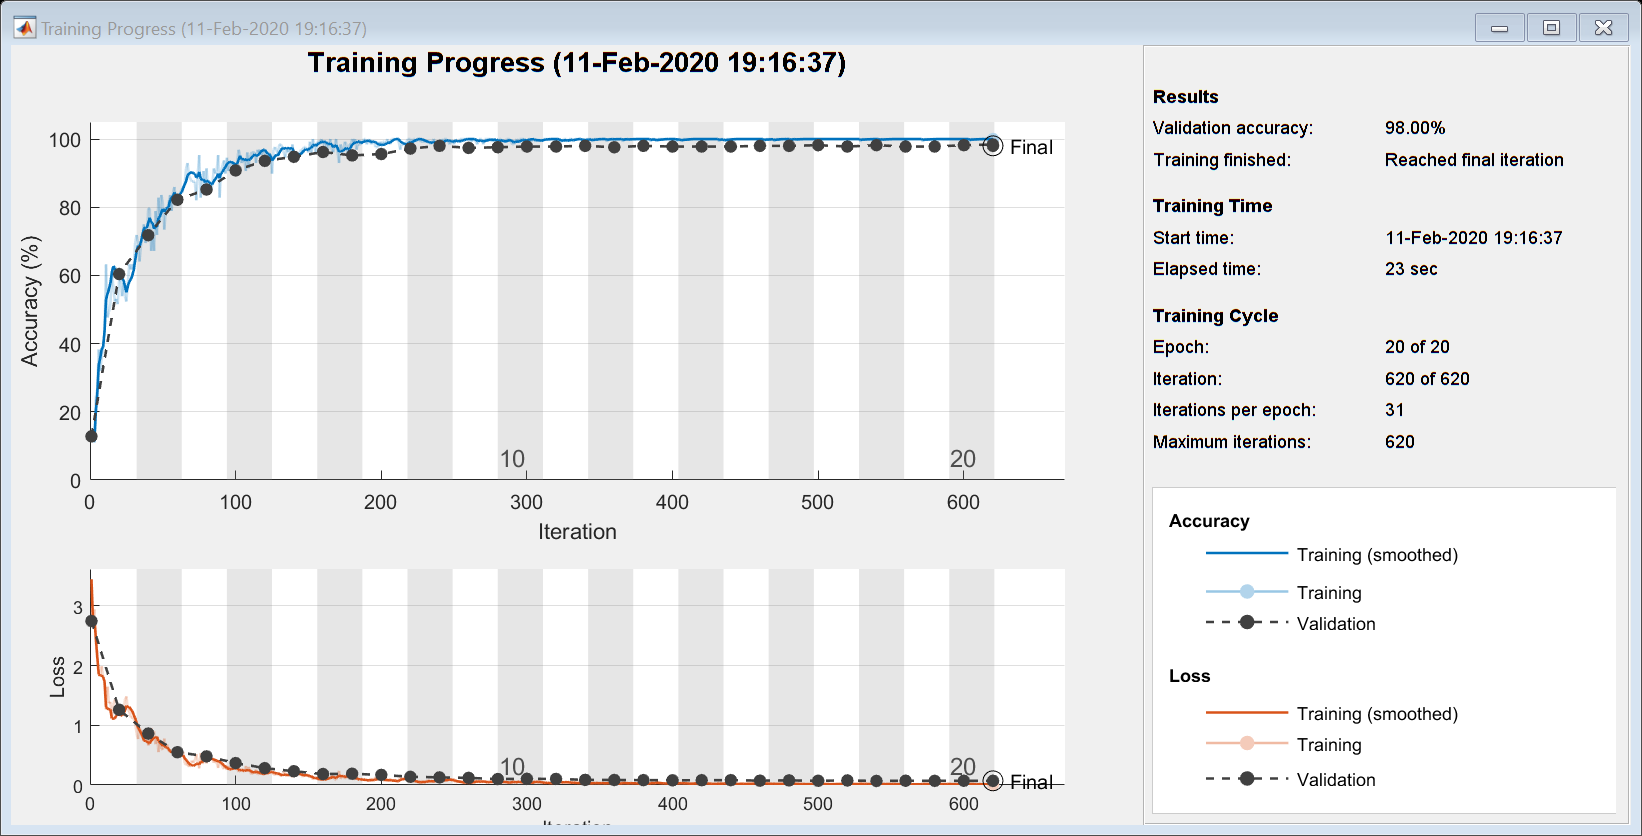

net = trainNetwork(augimds,layers_v1,options);

Run the trained network on the test set, which was not used to train the network, and predict the image labels (digits).

YPred = classify(net,XTest);

Calculate the accuracy. The accuracy is the ratio of the number of true labels in the test data matching the classifications from `classify` to the number of images in the test data.

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9940

*Copyright 2012 The MathWorks, Inc.*